Detect bursts is approacing a final draft. I am beginning testing here. 

## Defining directories

You need to add AQuA to your path in order to use its functions

softwareDir = 'Z:/.code/AQuA/'; %AQuA path
addpath(genpath(softwareDir));

%  read features from movies and put all the information in one structure called out
datDir = 'data/processed/v26/v26.aqua.data/'; %input directory where all of your processed movies are (aqua's .mat)
outDir = 'interim/v26.interim/';
velDir = ''


velDir =

  0×0 empty char array




spRes = 0.57998046875; %um/pix
tRes = 0.55578697729921; %sec/frame

## Read features from all movies, store in a structure called out

disp(pwd)

C:\Users\camer\Box\CMH\.repos\pfc


out = readFts(datDir);

     1

below
121219_V26_54um_2x-000_video_aqua
     2

below
121219_V26_59um_2x-000_video_aqua
     3

below
121219_V26_test2-000_video_aqua
     4

below
121219_V26_test2-000_video_aqua
     5

below
121619_10min_67um_nopupil_2x-002_video_aqua
     6

below
121619_10min_67um_nopupil_2x-002_video_aqua


Has read in the data from all aqua videos in v26 dir 

## Detect Bursts

[bursts, burstStats] = detectBurst(out, spRes, tRes, outDir, velDir)

ans = "Burst detected in video 1 at frame 112"

ans = "Burst detected in video 1 at frame 220"

ans = "Burst detected in video 1 at frame 349"

ans = "Burst detected in video 2 at frame 33"

ans = "Burst detected in video 2 at frame 60"

ans = "Burst detected in video 2 at frame 240"

ans = "Burst detected in video 2 at frame 269"

ans = "Burst detected in video 2 at frame 321"

ans = "Burst detected in video 3 at frame 35"

ans = "Burst detected in video 3 at frame 63"

ans = "Burst detected in video 3 at frame 154"

ans = "Burst detected in video 3 at frame 186"

ans = "Burst detected in video 3 at frame 295"

ans = "Burst detected in video 3 at frame 337"

ans = "Burst detected in video 3 at frame 392"

ans = "Burst detected in video 4 at frame 35"

ans = "Burst detected in video 4 at frame 64"

ans = "Burst detected in video 4 at frame 154"

ans = "Burst detected in video 4 at frame 189"

ans = "Burst detected in video 4 at frame 294"

ans = "Burst detected in video 4 at frame 339"

ans = "Burst detected in video 4 at frame 392"

Array indices must be positive integers or logical values.

Error in detectBurst (line 133)
                        if sum(numEvts(win) > (max(numEvts)*0.10)) == 0

Error occuring at line 133 

putting breakpoint and debugging

[bursts, burstStats] = detectBurst(out, spRes, tRes, outDir, velDir)

ans = "Burst detected in video 1 at frame 112"

ans = "Burst detected in video 1 at frame 220"

ans = "Burst detected in video 1 at frame 349"

ans = "Burst detected in video 2 at frame 33"

ans = "Burst detected in video 2 at frame 60"

ans = "Burst detected in video 2 at frame 240"

ans = "Burst detected in video 2 at frame 269"

ans = "Burst detected in video 2 at frame 321"

ans = "Burst detected in video 3 at frame 35"

ans = "Burst detected in video 3 at frame 63"

ans = "Burst detected in video 3 at frame 154"

ans = "Burst detected in video 3 at frame 186"

ans = "Burst detected in video 3 at frame 295"

ans = "Burst detected in video 3 at frame 337"

ans = "Burst detected in video 3 at frame 392"

ans = "Burst detected in video 4 at frame 35"

ans = "Burst detected in video 4 at frame 64"

ans = "Burst detected in video 4 at frame 154"

ans = "Burst detected in video 4 at frame 189"

ans = "Burst detected in video 4 at frame 294"

ans = "Burst detected in video 4 at frame 339"

ans = "Burst detected in video 4 at frame 392"

looks like error is coming from window setting making window start at 0 if peak is detected at exactly 20 frames in

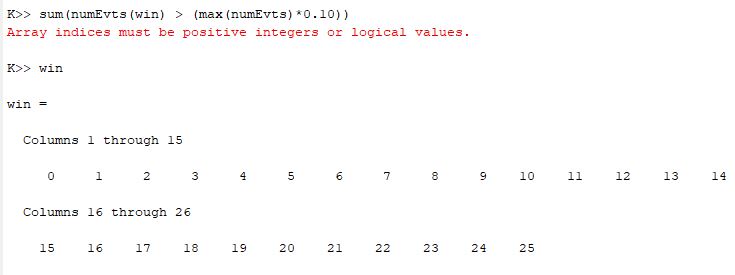

changing  to what is seen below (<= 20 for first condition rather than <20

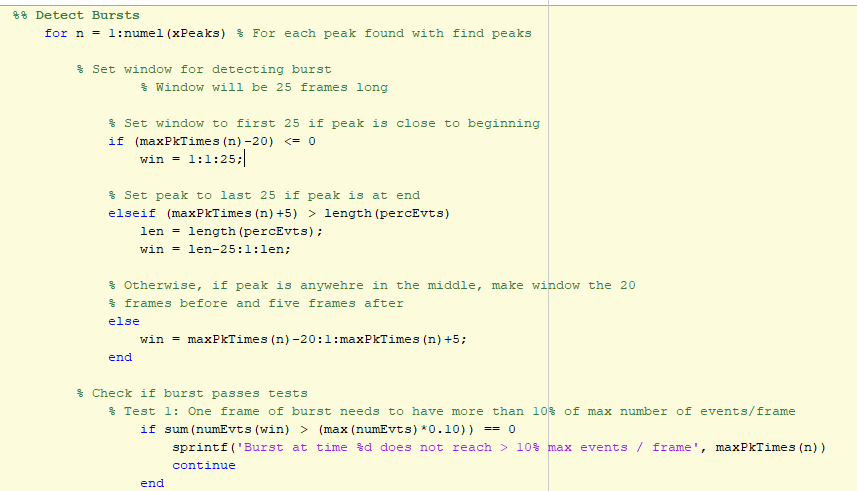

[bursts, burstStats] = detectBurst(out, spRes, tRes, outDir, velDir)

ans = "Burst detected in video 1 at frame 112"

ans = "Burst detected in video 1 at frame 220"

ans = "Burst detected in video 1 at frame 349"

ans = "Burst detected in video 2 at frame 33"

ans = "Burst detected in video 2 at frame 60"

ans = "Burst detected in video 2 at frame 240"

ans = "Burst detected in video 2 at frame 269"

ans = "Burst detected in video 2 at frame 321"

ans = "Burst detected in video 3 at frame 35"

ans = "Burst detected in video 3 at frame 63"

ans = "Burst detected in video 3 at frame 154"

ans = "Burst detected in video 3 at frame 186"

ans = "Burst detected in video 3 at frame 295"

ans = "Burst detected in video 3 at frame 337"

ans = "Burst detected in video 3 at frame 392"

ans = "Burst detected in video 4 at frame 35"

ans = "Burst detected in video 4 at frame 64"

ans = "Burst detected in video 4 at frame 154"

ans = "Burst detected in video 4 at frame 189"

ans = "Burst detected in video 4 at frame 294"

ans = "Burst detected in video 4 at frame 339"

ans = "Burst detected in video 4 at frame 392"

ans = "Burst detected in video 5 at frame 20"

ans = "Burst detected in video 5 at frame 59"

ans = "Burst detected in video 5 at frame 98"

ans = "Burst detected in video 5 at frame 124"

ans = "Burst detected in video 5 at frame 157"

ans = "Burst detected in video 5 at frame 203"

ans = "Burst detected in video 5 at frame 231"

ans = "Burst detected in video 5 at frame 272"

ans = "Burst detected in video 5 at frame 326"

ans = "Burst detected in video 5 at frame 354"

ans = "Burst detected in video 5 at frame 383"

ans = "Burst detected in video 5 at frame 411"

ans = "Burst detected in video 5 at frame 490"

ans = "Burst detected in video 5 at frame 517"

ans = "Burst detected in video 5 at frame 574"

ans = "Burst detected in video 5 at frame 609"

ans = "Burst detected in video 5 at frame 639"

ans = "Burst detected in video 5 at frame 680"

ans = "Burst detected in video 5 at frame 721"

ans = "Burst detected in video 5 at frame 749"

ans = "Burst detected in video 5 at frame 779"

ans = "Burst detected in video 5 at frame 816"

ans = "Burst detected in video 5 at frame 846"

ans = "Burst detected in video 5 at frame 892"

ans = "Burst detected in video 5 at frame 934"

ans = "Burst detected in video 5 at frame 976"

ans = "Burst detected in video 5 at frame 1007"

ans = "Burst detected in video 5 at frame 1043"

ans = "Burst detected in video 5 at frame 1069"

ans = "Burst detected in video 6 at frame 32"

ans = "Burst detected in video 6 at frame 60"

ans = "Burst detected in video 6 at frame 96"

ans = "Burst detected in video 6 at frame 132"

ans = "Burst detected in video 6 at frame 159"

ans = "Burst detected in video 6 at frame 198"

ans = "Burst detected in video 6 at frame 234"

ans = "Burst detected in video 6 at frame 272"

ans = "Burst detected in video 6 at frame 326"

ans = "Burst detected in video 6 at frame 355"

ans = "Burst detected in video 6 at frame 409"

ans = "Burst detected in video 6 at frame 476"

ans = "Burst detected in video 6 at frame 517"

ans = "Burst detected in video 6 at frame 573"

ans = "Burst detected in video 6 at frame 609"

ans = "Burst detected in video 6 at frame 653"

ans = "Burst detected in video 6 at frame 703"

ans = "Burst detected in video 6 at frame 761"

ans = "Burst detected in video 6 at frame 795"

ans = "Burst detected in video 6 at frame 823"

ans = "Burst detected in video 6 at frame 853"

ans = "Burst detected in video 6 at frame 883"

ans = "Burst detected in video 6 at frame 934"

ans = "Burst detected in video 6 at frame 988"

ans = "Burst detected in video 6 at frame 1027"

ans = "Burst detected in video 6 at frame 1069"

bursts = 1×6 cell array
    {3×2 double}    {5×2 double}    {7×2 double}    {7×2 double}    {29×2 double}    {26×2 double}


burstStats = struct with fields:
      numEvts: {[1×540 double]  [1×427 double]  [1×427 double]  [1×427 double]  [1×1080 double]  [1×1080 double]}
     percEvts: {[1×540 double]  [1×427 double]  [1×427 double]  [1×427 double]  [1×1080 double]  [1×1080 double]}
     snumEvts: {[1×299 double]  [1×236 double]  [1×236 double]  [1×236 double]  [1×599 double]  [1×599 double]}
    spercEvts: {[1×299 double]  [1×236 double]  [1×236 double]  [1×236 double]  [1×599 double]  [1×599 double]}
